Signal parameters

Fs = 1000;
T = 1/Fs;
L = 1000;
t = (0:L-1)*T;

Generate Signal

x1 = cos(2*pi*50*t);
x2 = cos(2*pi*150*t);
x3 = cos(2*pi*300*t);

X = [x1; x2; x3];

plot

for i = 1:3
    subplot(3,1,i)
    plot(t(1:100), X(i, 1:100))
    title(['Row', num2str(i), ' in the Time Domain'])
end

fft

n = 2^nextpow2(L);
dim = 2;
Y = fft(X, n, dim);

P2 = abs(Y/L);
P1 = P2(:, 1:n/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

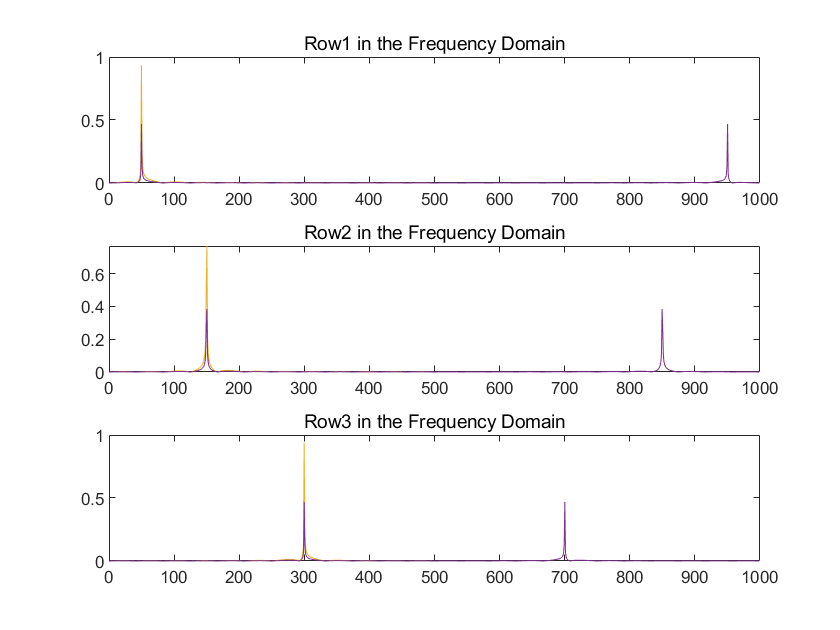

for i=1:3
    subplot(3,1,i)
    plot(0:(Fs/n):(Fs/2-Fs/n), P1(i,1:n/2))
    hold on
    plot(0:Fs/n:Fs-Fs/n, P2(i,:))
    title(['Row', num2str(i), ' in the Frequency Domain'])
end